
clearvars;

% =========================================================================
% DEFINE LITERALS
% =========================================================================
    

% medium parameters
c0              = 1500;     % sound speed [m/s]
rho0            = 1000;     % density [kg/m^3]
u               = 0.04;

% source parameters
source_f0       = 500000;   % source frequency [Hz]
source_roc      = 15e-3;    % bowl radius of curvature [m]
source_diameter = 20e-3;    % bowl aperture diameter [m]
source_mag      = rho0*c0*u;% source pressure [Pa]
offset          = source_roc - sqrt((source_roc^2)-(source_diameter/2)^2);

% grid parameters
axial_size      = 64e-3;    % total grid size in the axial dimension [m]
lateral_size    = 32e-3;  % total grid size in the lateral dimension [m]

% computational parameters
ppw             = 10;        % number of points per wavelength
t_end           = 120e-6;    % total compute time [s] (this must be long enough to reach steady state)
record_periods  = 3;        % number of periods to record
cfl             = 0.05;     % CFL number

% =========================================================================
% RUN SIMULATION
% =========================================================================

% --------------------
% GRID
% --------------------

% calculate the grid spacing based on the PPW and F0
dx = c0 / (ppw * source_f0);   % [m]

source_x_offset = round(offset/dx); %grid points for offset of source 

% compute the size of the grid
Nx = roundEven(axial_size / dx) 

Nx = 214

%+ source_x_offset;
Ny = roundEven(lateral_size / dx);
% Nx = 120;
% Ny = 120;


% create the computational grid
kgrid = kWaveGrid(Nx, dx, Ny, dx);

% compute points per temporal period
PPP = round(ppw / cfl);

% compute corresponding time spacing
dt = 1 / (PPP * source_f0);

% create the time array using an integer number of points per period
Nt = round(t_end / dt);
kgrid.setTime(Nt, dt);

% calculate the actual CFL and PPW
disp(['PPW = ' num2str(c0 / (dx * source_f0))]);

PPW = 10


disp(['CFL = ' num2str(c0 * dt / dx)]);

CFL = 0.05


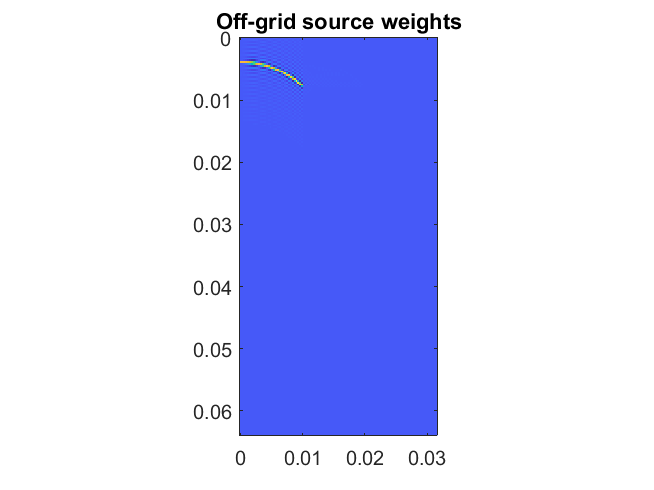


% --------------------
% SOURCE
% --------------------

% create time varying source
source_sig = createCWSignals(kgrid.t_array, source_f0, source_mag, 0);

% create empty kWaveArray
karray = kWaveArray('Axisymmetric', true, 'BLITolerance', 0.01, 'UpsamplingRate', 10);

% set bowl position and orientation
arc_pos = [kgrid.x_vec(1) + source_x_offset * kgrid.dx, 0];
focus_pos = [kgrid.x_vec(end), 0];

% add arc shaped element
karray.addArcElement(arc_pos, source_roc, source_diameter, focus_pos);

% assign binary mask
source.p_mask = karray.getArrayBinaryMask(kgrid);

% assign source signals
source.p = karray.getDistributedSourceSignal(kgrid, source_sig);

% plot grid weights
grid_weights = karray.getArrayGridWeights(kgrid);
figure;
imagesc(kgrid.y_vec - kgrid.y_vec(1), kgrid.x_vec - kgrid.x_vec(1), grid_weights);
axis image;
title('Off-grid source weights');

Running k-Wave simulation...
  start time: 30-Apr-2022 01:52:33
  reference sound speed: 1500m/s
  dt: 10ns, t_end: 119.99us, time steps: 12000
  input grid size: 214 by 106 grid points (64.2 by 31.8mm)
  maximum supported frequency: 2.5MHz
  expanding computational grid...
  computational grid size: 256 by 128 grid points
  casting variables to single type...
  precomputation completed in 5.8443s
  starting time loop...
  estimated simulation time 12min 12.72s...


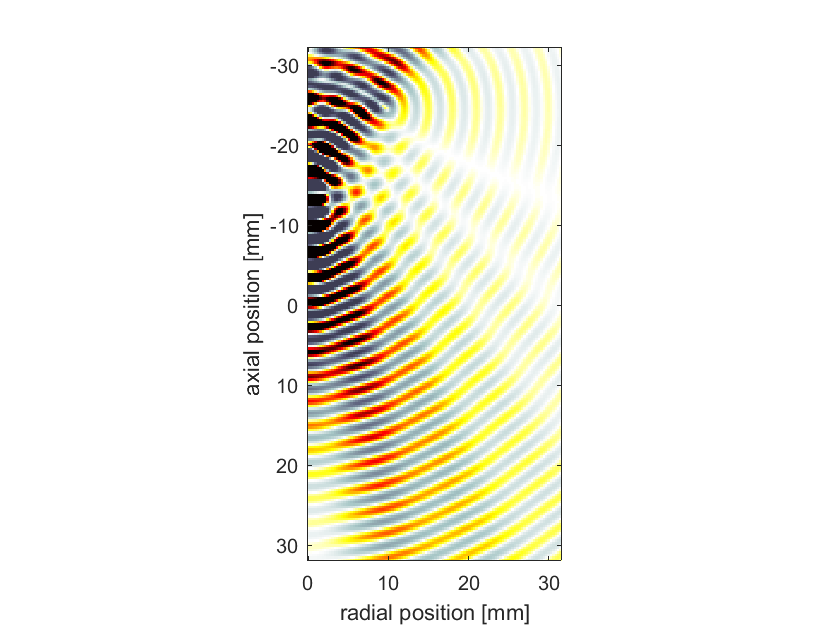

  simulation completed in 14min 13.1568s
  total computation time 14min 21.159s


    
% --------------------
% MEDIUM
% --------------------

% assign medium properties
medium.sound_speed = c0;
medium.density = rho0;

% --------------------
% SENSOR
% --------------------

% set sensor mask to record central plane, not including the source point
sensor.mask = zeros(Nx, Ny);
sensor.mask(:, :) = 1;

% record the pressure
sensor.record = {'p'};

% --------------------
% SIMULATION
% --------------------

% set input options
input_args = {...
    'PMLSize', 'auto', ...
    'PMLInside', false, ...
    'PlotPML', false, ...
    'DisplayMask', 'off'};

% run code

sensor_data = kspaceFirstOrderAS(kgrid, medium, source, sensor, ...
    input_args{:}, ...
    'DataCast', 'single', ...
    'PlotScale', [-1, 1] * source_mag);


% extract amplitude from the sensor data
amp = extractAmpPhase(sensor_data.p, 1/kgrid.dt, source_f0, ...
    'Dim', 2, 'Window', 'Rectangular', 'FFTPadding', 1);

% reshape data
amp = reshape(amp, Nx, Ny);

% extract pressure on axis
amp_on_axis = amp(:, 1);

% define axis vectors for plotting
x_vec = kgrid.x_vec(source_x_offset + 2:end, :) - kgrid.x_vec(source_x_offset + 1);
y_vec = kgrid.y_vec - kgrid.y_vec(1);

% =========================================================================
% ANALYTICAL SOLUTION
% =========================================================================

% calculate the wavenumber
k = 2 * pi * source_f0 ./ c0;

% % define radius and axis
% x_max = (Nx * dx);
% x_ref = 0:x_max/10000:x_max;
% 
% % calculate analytical solution
% p_ref_axial = focusedBowlONeil(source_roc, source_diameter, source_mag / (c0 * rho0), source_f0, c0, rho0, x_ref, []);
% 
% % calculate analytical solution at exactly the same points as k-Wave
% p_ref_axial_kw = focusedBowlONeil(source_roc, source_diameter, source_mag / (c0 * rho0), source_f0, c0, rho0, x_vec, []);
% 
% % calculate error
% L2_error = 100 * sqrt( sum( (p_ref_axial_kw(:) - amp_on_axis(:)).^2 ) / sum( p_ref_axial_kw(:).^2 ) );
% Linf_error = 100 * max(abs(p_ref_axial_kw(:) - amp_on_axis(:))) / max(p_ref_axial_kw(:));
% % =========================================================================
% % Extracting Pressure and Time Data
% =========================================================================

x_vec = kgrid.x_vec(2:end, :) - kgrid.x_vec(1);

timeperiod= 0:dt:t_end-dt;
periodofwave = 1/source_f0;
cyclelength = periodofwave/dt;
timeindex = Nt-(cyclelength-1);
wavetime = timeperiod(timeindex:Nt);
samplingfrequency = 1/dt;
freqv = (0:cyclelength/2-1)*samplingfrequency/cyclelength;
FFTarray = [];
FFTmag = [];
for i=1:Nx-1
    pressuretime = sensor_data.p(i, 1:Nt);
    cycleextract = pressuretime(timeindex:Nt);
    FFT = fft(cycleextract);

    %symmetric so remove second half
    FFT = FFT(1:cyclelength/2);
    
    %magnitude of fft
    mFFT = (abs(FFT));
    scaledFFT = mFFT*(2/PPP);
    [FFTpeak, FFTindex] = max(scaledFFT);
    peakfreq = freqv(FFTindex);
    FFTarray = [FFTarray,peakfreq];
    FFTmag = [FFTmag,FFTpeak];
end





% 
% % =========================================================================
% %%% ATTENUATION
% % =========================================================================
% 
% 
% % =========================================================================
% % DEFINE LITERALS
% % =========================================================================
%     clearvars
% 
% % medium parameters
% c0              = 1500;     % sound speed [m/s]
% rho0            = 1000;     % density [kg/m^3]
% u               = 0.04;
% 
% % source parameters
% source_f0       = 500000;   % source frequency [Hz]
% source_roc      = 15e-3;    % bowl radius of curvature [m]
% source_diameter = 20e-3;    % bowl aperture diameter [m]
% source_mag      = rho0*c0*u;% source pressure [Pa]
% offset          = source_roc - sqrt((source_roc^2)-(source_diameter/2)^2);
% 
% % grid parameters
% axial_size      = 100e-3;    % total grid size in the axial dimension [m]
% lateral_size    = 40e-3/2;  % total grid size in the lateral dimension [m]
% 
% % computational parameters
% ppw             =10;        % number of points per wavelength
% t_end           = 240e-6;    % total compute time [s] (this must be long enough to reach steady state)
% record_periods  = 3;        % number of periods to record
% cfl             = 0.05;     % CFL number
% 
% % =========================================================================
% % RUN SIMULATION
% % =========================================================================
% 
% % --------------------
% % GRID
% % --------------------
% 
% % calculate the grid spacing based on the PPW and F0
% dx = c0 / (ppw * source_f0);   % [m]
% 
% source_x_offset = round(offset/dx); %grid points for offset of source 
% 
% % compute the size of the grid
% Nx = roundEven(axial_size / dx) + source_x_offset;
% Ny = roundEven(lateral_size / dx);
% 
% % create the computational grid
% kgrid = kWaveGrid(Nx, dx, Ny, dx);
% 
% % compute points per temporal period
% PPP = round(ppw / cfl);
% 
% % compute corresponding time spacing
% dt = 1 / (PPP * source_f0);
% 
% % create the time array using an integer number of points per period
% Nt = round(t_end / dt);
% kgrid.setTime(Nt, dt);
% 
% % calculate the actual CFL and PPW
% disp(['PPW = ' num2str(c0 / (dx * source_f0))]);
% disp(['CFL = ' num2str(c0 * dt / dx)]);
% 
% % --------------------
% % SOURCE
% % --------------------
% 
% % create time varying source
% source_sig = createCWSignals(kgrid.t_array, source_f0, source_mag, 0);
% 
% % create empty kWaveArray
% karray = kWaveArray('Axisymmetric', true, 'BLITolerance', 0.01, 'UpsamplingRate', 10);
% 
% % set bowl position and orientation
% arc_pos = [kgrid.x_vec(1) + source_x_offset * kgrid.dx, 0];
% focus_pos = [kgrid.x_vec(end), 0];
% 
% % add arc shaped element
% karray.addArcElement(arc_pos, source_roc, source_diameter, focus_pos);
% 
% % assign binary mask
% source.p_mask = karray.getArrayBinaryMask(kgrid);
% 
% % assign source signals
% source.p = karray.getDistributedSourceSignal(kgrid, source_sig);
% 
% % plot grid weights
% grid_weights = karray.getArrayGridWeights(kgrid);
% figure;
% imagesc(kgrid.y_vec - kgrid.y_vec(1), kgrid.x_vec - kgrid.x_vec(1), grid_weights);
% axis image;
% title('Off-grid source weights');
%     
% % --------------------
% % MEDIUM
% % --------------------
% 
% % assign medium properties
% medium.sound_speed = c0;
% medium.density = rho0;
% medium.alpha_power = 2;
% medium.alpha_coeff = 5;
% 
% % --------------------
% % SENSOR
% % --------------------
% 
% % set sensor mask to record central plane, not including the source point
% sensor.mask = zeros(Nx, Ny);
% sensor.mask(source_x_offset + 2:end, :) = 1;
% 
% % record the pressure
% sensor.record = {'p'};
% 
% % --------------------
% % SIMULATION
% % --------------------
% 
% % set input options
% input_args = {...
%     'PMLSize', 'auto', ...
%     'PMLInside', false, ...
%     'PlotPML', false, ...
%     'DisplayMask', 'off'};
% 
% % run code
% 
% sensor_data = kspaceFirstOrderAS(kgrid, medium, source, sensor, ...
%     input_args{:}, ...
%     'DataCast', 'single', ...
%     'PlotScale', [-1, 1] * source_mag);
% 
% % extract amplitude from the sensor data
% amp = extractAmpPhase(sensor_data.p, 1/kgrid.dt, source_f0, ...
%     'Dim', 2, 'Window', 'Rectangular', 'FFTPadding', 1);
% 
% % reshape data
% amp = reshape(amp, Nx - source_x_offset - 1, Ny);
% 
% % extract pressure on axis
% amp_on_axis = amp(:, 1);
% 
% % define axis vectors for plotting
% x_vec = kgrid.x_vec(source_x_offset + 2:end, :) - kgrid.x_vec(source_x_offset + 1);
% y_vec = kgrid.y_vec - kgrid.y_vec(1);
% 
% % =========================================================================
% % ANALYTICAL SOLUTION
% % =========================================================================
% 
% % calculate the wavenumber
% k = 2 * pi * source_f0 ./ c0;
% 
% % define radius and axis
% x_max = (Nx * dx);
% x_ref = 0:x_max/10000:x_max;
% 
% % calculate analytical solution
% p_ref_axial = focusedBowlONeil(source_roc, source_diameter, source_mag / (c0 * rho0), source_f0, c0, rho0, x_ref, []);
% 
% % calculate analytical solution at exactly the same points as k-Wave
% p_ref_axial_kw = focusedBowlONeil(source_roc, source_diameter, source_mag / (c0 * rho0), source_f0, c0, rho0, x_vec, []);
% 
% % calculate error
% L2_error = 100 * sqrt( sum( (p_ref_axial_kw(:) - amp_on_axis(:)).^2 ) / sum( p_ref_axial_kw(:).^2 ) );
% Linf_error = 100 * max(abs(p_ref_axial_kw(:) - amp_on_axis(:))) / max(p_ref_axial_kw(:));
% % =========================================================================
% % Extracting Pressure and Time Data
% % =========================================================================
% x_vec = kgrid.x_vec(2:end, :) - kgrid.x_vec(1);
% 
% timeperiod= 0:dt:t_end-dt;
% periodofwave = 1/source_f0;
% cyclelength = periodofwave/dt;
% timeindex = Nt-(cyclelength-1);
% wavetime = timeperiod(timeindex:Nt);
% samplingfrequency = 1/dt;
% freqv = (0:cyclelength/2-1)*samplingfrequency/cyclelength;
% FFTarray = [];
% FFTmag1 = [];
% for i=1:Nx-1
%     pressuretime = sensor_data.p(i, 1:Nt);
%     cycleextract = pressuretime(timeindex:Nt);
%     FFT = fft(cycleextract);
% 
%     %symmetric so remove second half
%     FFT = FFT(1:cyclelength/2);
%     
%     %magnitude of fft
%     mFFT = (abs(FFT));
%     scaledFFT = mFFT*(2/PPP);
%     [FFTpeak, FFTindex] = max(scaledFFT);
%     peakfreq = freqv(FFTindex);
%     FFTarray = [FFTarray,peakfreq];
%     FFTmag1 = [FFTmag1,FFTpeak];
% end
% % =========================================================================
% % VISUALISATION
% % =========================================================================
% % load('FFTmag')
% % load('x_vec')
% % plot fft 
% figure;
% plot(x_vec*10^3,FFTmag/10^3)
% ylabel('Magnitude of Acoustic Pressure at Peak Frequency P(f) [kPa]')
% xlabel('Axial Position (mm)')
% title('Acoustic Pressure at Peak Frequency on Axial Positions after reaching steady-state with a bowl piston')
% hold on
% plot(x_vec*10^3,FFTmag1/10^3)
% hold off


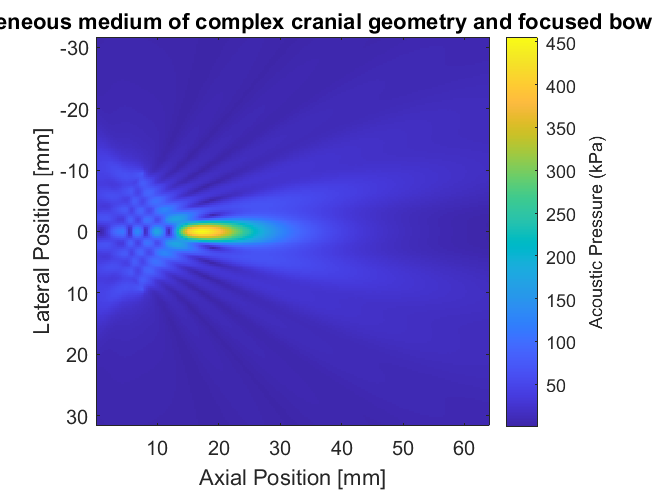

% plot the pressure field 

% duplicate the pressure field
amp = [flip(amp(:, 2:end), 2), amp];
y_vec = [-flip(y_vec(2:end)); y_vec];
figure;
imagesc(1e3 * x_vec, 1e3 * y_vec, 1e-3*amp.');
xlabel('Axial Position [mm]');
ylabel('Lateral Position [mm]');
axis image;
title('Acoustic Pressure Field with a heterogeneous medium of complex cranial geometry and focused bowl source generated using k-Wave');
a = colorbar;
a.Label.String = 'Acoustic Pressure (kPa)';

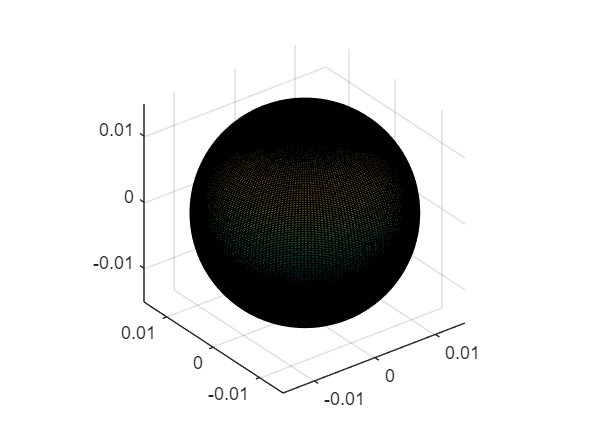


%% plane of skull
%sensor.mask(:, :,Nz/2 + 1) = 1;
%xplane = squeeze(medium.sound_speed(:, :,Nz/2 + 1));
%% Variables %%
m=41;
a=0.01;
b=0.12;
w = 214;
%w = 104;
c = 1500;%speed of sound
f = 500000; %frequency
%k = (2*pi*f/c);%wave number
A = (5*100)/(20*log10(exp(1)));
B = 2;
alpha = A*((f*1e-6)^B);
omega = (2*pi*f);
k = omega/c;%complex wave number
kcomplex = k -(1i*alpha);
%% Non attenuated
k = (2*pi*f/c);%wave number
ww = c/f; %wavelength = speed/frequency
p0 = 1000; %density of water
c = omega/kcomplex;
%% 3D coordinates %%
u = [0.04,0,0];%velocity vector
n = [1, 0, 0]; %normal vector with positive x axis being the axis of propagation
v = dot(u,n); %dot product of velocity vector with normal vector
% x2=linspace(0,0.1,w);
% y2=linspace(-0.02,0.02,w/1.5);
% z2=linspace(0,0.1,w);
% [X,Y,Z]=meshgrid(x2,y2,z2);
x2=linspace(0,0.64,w);
y2=linspace(-0.032,0.032,w);
z2=linspace(0,0.64,w);
[X,Y,Z]=meshgrid(x2,y2,z2);
sz = size(X);
P = zeros(sz); %creates matrix for receiver coordinates to sum all the values calculated below for each coordinate
%% Bowl %%
[XA,YA,ZA] = sphere(200);
radiusofcurvature = 0.015;
diameterofaperture = 0.02;
polarangle = asin((diameterofaperture/2)/radiusofcurvature);
h = radiusofcurvature - sqrt((radiusofcurvature^2)-(diameterofaperture/2)^2);
bowlarea = pi*((diameterofaperture/2)^2+h^2);
sf=surf(radiusofcurvature.*XA,radiusofcurvature.*YA,radiusofcurvature.*ZA);
Xa = get(sf, 'XData')+radiusofcurvature;
Ya = get(sf, 'YData');
Za = get(sf, 'ZData');
axis equal

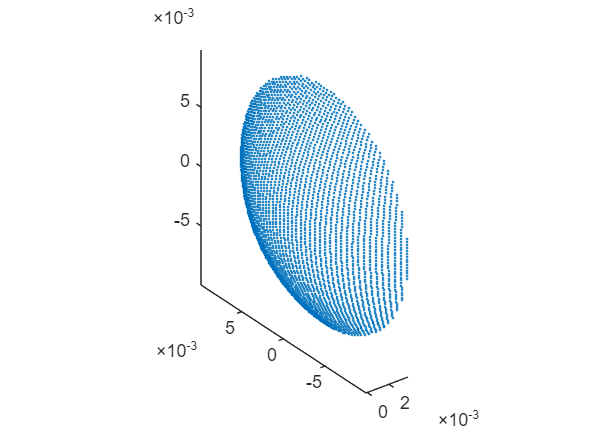

spherel = length(Xa)^2;
xa=reshape(Xa,spherel,1);
ya=reshape(Ya,spherel,1);
za=reshape(Za,spherel,1);
q = length(xa);
spherematrix = [xa,ya,za];
indices = find(spherematrix(:,1)>h);
spherematrix(indices,:)=[];
xb = spherematrix(:,1);
yb = spherematrix(:,2);
zb = spherematrix(:,3);
plot3(xb,yb,zb,'o','MarkerSize',1)
axis equal


%% Pressure calculation %%
g = bowlarea/length(xb);
%% Pressure calculation %%
%alpha = 5*((f*1e-6)^B);
t = 1;
% for j=1:length(xb)
%     P = P + ((((1i*p0*c*kcomplex)/(2*pi)).*((((exp((sqrt((((xb(j)-X).^2)+(((yb(j))-Y).^2)+((zb(j))-Z).^2))).*k.*-1i))./(sqrt(((xb(j)-X).^2)+(((yb(j))-Y).^2)+((zb(j)-Z).^2)))).*v.*g))).*exp(1i*((k*X)-(omega*t))).*exp((-alpha.*X)));
% end
for j=1:length(xb)
    P = P + ((((1i*p0*c*k)/(2*pi)).*((((exp((sqrt((((xb(j)-X).^2)+(((yb(j))-Y).^2)+((zb(j))-Z).^2))).*k.*-1i))./(sqrt(((xb(j)-X).^2)+(((yb(j))-Y).^2)+((zb(j)-Z).^2)))).*v.*g))).*exp(1i*((k*X)-(omega*t))).*exp((-alpha.*X)));
end
% for j=1:length(xb)
%     P = P + ((((1i*p0*c*kcomplex)/(2*pi)).*((((exp(-1i.*((omega*t)-(sqrt((((xb(j)-X).^2)+(((yb(j))-Y).^2)+((zb(j))-Z).^2))).*k)))./(sqrt(((xb(j)-X).^2)+(((yb(j))-Y).^2)+((zb(j)-Z).^2)))).*v.*g))).*exp((-alpha.*(sqrt((((xb(j)-X).^2)+(((yb(j))-Y).^2)+((zb(j))-Z).^2))))));
% end
PP = abs(P);
pd = squeeze(PP(102,:,1));
%pd = squeeze(PP(35,:,1));
MM = [];
plot(x2*10^3,pd/10^3);
title('Comparison of the Magnitude of Acoustic Pressure of Bowl Source from Rayleigh Integral and k-Wave')
xlabel('Axial Position (mm)')
ylabel('Acoustic Pressure [kPa]')
xlim([0 54])
hold on
plot(x_vec*10^3,FFTmag/10^3)
%plot(x_vec*10^3,FFTmag1/10^3)
legend('Rayleigh Integral Solution','Non-attenuated on-axis pressure','k-Wave Solution')
hold off
% positionarrayanalysis = positionarray(2:280);
% x2analysis = x2(2:280);
% pdanalysis = pd(2:280);
% FFTanalysis = FFTmag(2:280);
% D = (pdanalysis-FFTanalysis).^2;
% S1= sum(D);
% S2 = sum((pdanalysis).^2);
% ctest = 100*(sqrt(S1/S2));
% MM = [ctest,MM];
% plot(MM);

%% Plotting slice of xy plane %%
xslice=[];
yslice=[];
zslice=0;
slice(X*1e03,Y*1e03,Z*1e03,PP*1e-03,xslice,yslice,zslice)
shading flat
a = colorbar;
a.Label.String = 'Acoustic Pressure (kPa)';

title('Acoustic Pressure field from a bowl source in xy plane')
xlabel('Axis of propagation (mm)')
ylabel('Lateral position (mm)')


t = 0:0.001:2;
testtt = (exp(1i*omega*t))
plot(t,testtt)

ttttt = exp(-1*log(10)*5*((f*1e-6)^B)/20)
tt = exp(-alpha)